# **Leg Circle Analysis**

## **Data Analysis**

### **Load, Trim, and Filter Data**

% Load Data
[LegMotionData]=ParseMatlabApp('Data/leg_circle_normal.mat');

% Trim data to isolate exercise
time = LegMotionData.t_Accel(25:105);
leg_acceleration = LegMotionData.Accel(25:105, :);

% Apply Moving Average Filter
x = leg_acceleration(:,1);
y = leg_acceleration(:,2);
z = leg_acceleration(:,3);
leg_accelerationx = [x(1) + x(2); x(1:end-2) + x(2:end-1) + x(3:end); x(end-1) + x(end)]/3;
leg_accelerationy = [y(1) + y(2); y(1:end-2) + y(2:end-1) + y(3:end); y(end-1) + y(end)]/3;
leg_accelerationz = [z(1) + z(2); z(1:end-2) + z(2:end-1) + z(3:end); z(end-1) + z(end)]/3;
leg_acceleration_filtered = [leg_accelerationx leg_accelerationy leg_accelerationz];

### Plot Filtered Time Domain

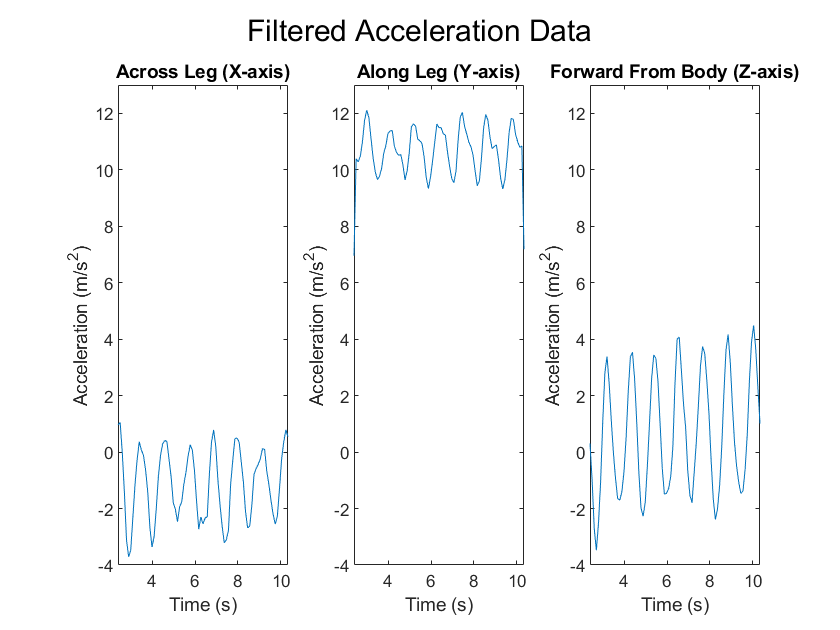

% Plot Time Domain
% Plot Raw Data
% makeAccelerometerPlots([time,leg_acceleration], {'Across Leg Raw', 'Along Leg Raw', 'In direction of Toes'})

% Plot Filtered Data
% Subplot 1
clf;
p1 = subplot(131);
plot(time, leg_accelerationx)
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
title('Across Leg (X-axis)')

% Subplot 2
p2 = subplot(132);
plot(time, leg_accelerationy)
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
title('Along Leg (Y-axis)')

% Subplot 3
p3 = subplot(133);
plot(time, leg_accelerationz)
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
title('Forward From Body (Z-axis)')

sgtitle('Filtered Acceleration Data') 
linkaxes([p1, p2, p3]);

### Calculate & Plot Fourier Transformations

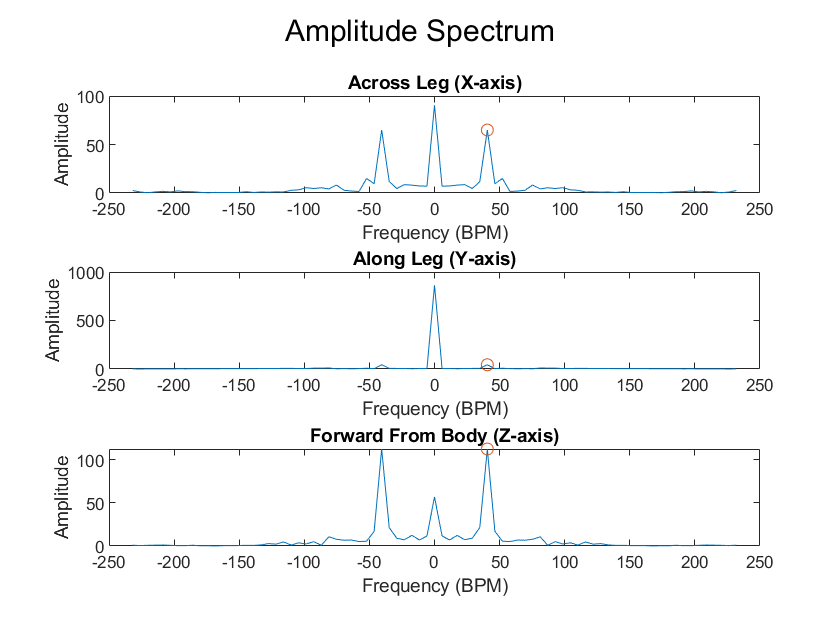

% Calculate Fourier Transform Frequencies
N = length(time);
time_elapsed = time(end);
Fs = length(time)/time_elapsed;
frequencies_shifted = linspace(-Fs*pi , Fs*(pi - 2*pi/N), N) + Fs*pi/N*mod(N,2);
%^^ based on lowest and highest frequencies we found above
%^^ mod is to account for if its even or odd
fourier_frequenciesx = fftshift(fft(leg_acceleration_filtered(:,1)));
fourier_frequenciesy = fftshift(fft(leg_acceleration_filtered(:,2)));
fourier_frequenciesz = fftshift(fft(leg_acceleration_filtered(:,3)));

% Plot Fourier Transformations
% converts from rad/s to bpm
convert_to_bpm = 1/0.10471975499997;

% Subplot 1
clf;
subplot(3, 1, 1);
% find two highest peaks
[pksx,locsx] = findpeaks(abs(fourier_frequenciesx), frequencies_shifted*convert_to_bpm, 'SortStr', 'descend', 'Npeaks', 2);
% find highest peak excluding 0 
[max_frequencyx, max_amplitudex] = find_largest_frequency(locsx, pksx);
% plot ft and peak excluding 0 
plot(frequencies_shifted*convert_to_bpm,abs(fourier_frequenciesx),max_frequencyx,max_amplitudex, 'o');
xlabel('Frequency (BPM)')
ylabel('Amplitude')
title("Across Leg (X-axis)")

% Subplot 2
subplot(3, 1, 2);
% find two highest peaks
[pksy,locsy] = findpeaks(abs(fourier_frequenciesy), frequencies_shifted*convert_to_bpm, 'SortStr', 'descend', 'Npeaks', 2);
% find highest peak excluding 0 
[max_frequencyy, max_amplitudey] = find_largest_frequency(locsy, pksy);
% plot ft and peak excluding 0 
plot(frequencies_shifted*convert_to_bpm,abs(fourier_frequenciesy), max_frequencyy, max_amplitudey, 'o');
xlabel('Frequency (BPM)')
ylabel('Amplitude')
title("Along Leg (Y-axis)")

% Subplot 3
subplot(3, 1, 3);
% find two highest peaks
[pksz,locsz] = findpeaks(abs(fourier_frequenciesz), frequencies_shifted*convert_to_bpm, 'SortStr', 'descend', 'Npeaks', 2);
% find highest peak excluding 0
[max_frequencyz, max_amplitudez] = find_largest_frequency(locsz, pksz);
% plot ft and peak excluding 0 
plot(frequencies_shifted*convert_to_bpm,abs(fourier_frequenciesz), max_frequencyz, max_amplitudez, 'o');
xlabel('Frequency (BPM)')
ylabel('Amplitude')
title('Forward From Body (Z-axis)')

sgtitle('Amplitude Spectrum') 

## Performance Feedback

### Tempo

% find tempo by averaging the frequency (in bpm) of the exercise in all
% excluding y axis because the y movement is essentially static
tempo_actual = (max_frequencyx + max_frequencyz)/2;
% get tempo feedback
tempo_feedback = tempo_analysis(50, tempo_actual)

tempo_feedback = "Your tempo is great."

### Shape

% find ratio of the x axis highest amplitude to the z axis highest
% amplitude
ratio_XtoZ = max_amplitudex/max_amplitudez;

% get feedback on the shape of the exercise
% threshold for the ratio to be considered too horizontal or too vertical
ratio_threshold = 2;
shape_feedback = shape_analysis(ratio_XtoZ, ratio_threshold)

shape_feedback = "Your circle shape is looking great!"